*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 4 : Plug a custom scheduler into the 5G network model**

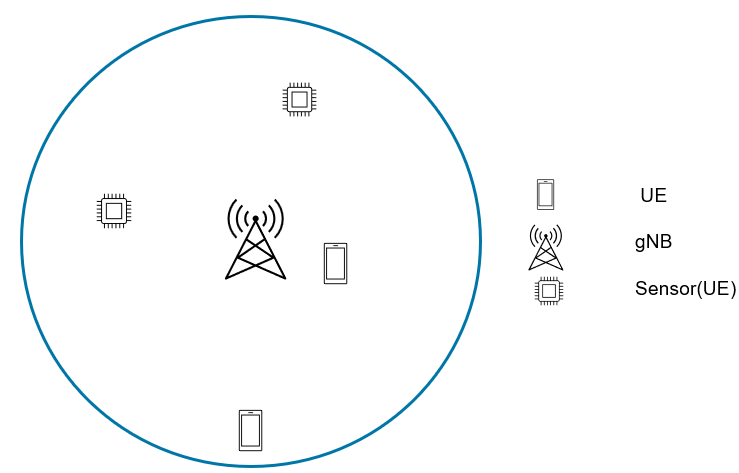

This exercise shows how to create and plug a custom resource-scheduling strategy in a 5G network. The goals are:

- Introduce custom traffic patterns and mobility profiles to selected 5G nodes.

- Prioritize these nodes during resource scheduling using a custom scheduling algorithm.

- Visualize and quantify the impact of the custom scheduler  

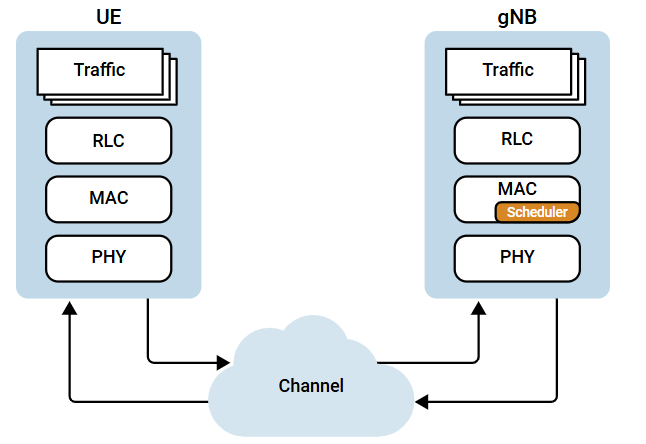

Check if the Communications Toolbox™ Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

Create a wireless network simulator.

all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 
rng("default")           % Reset the random number generator
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities

numFrameSimulation = 200; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;
trafficType = "High Priority Traffic";

# Task #1/3 Create a high priority traffic model 

% Define traffic type
% Use networkTrafficOnOff() function to configure application layer traffic
% Write configuration in a variable named "ulApp_1"
% Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% onTime = inf
% OffTime = 0
% DataRate = 12 kpbs
% PacketSize = 30
% GeneratePacket=true

% <enter code below>
% ulApp_1 =

plotTrafficPattern(numFrameSimulation,ulApp_1);

Instances of periodic traffic: 

- Include sensor networks reporting at fixed intervals

- Heartbeat messages in network protocols

- Timed updates in control systems

ulApp_2 = networkTrafficOnOff(OnTime=Inf,DataRate=12,PacketSize=30,GeneratePacket=true);

#### Create a gNB node 

gNB = nrGNB(Position=[0 0 10],CarrierFrequency=2.6e9,ChannelBandwidth=5e6,SubcarrierSpacing=15e3,ReceiveGain=11, ...
    NumTransmitAntennas=1,NumReceiveAntennas=1,SRSPeriodicityUE=40);

#### Custom scheduler 

The New Radio (NR) scheduler is a crucial component of the 5G NR protocol stack, efficiently allocating radio resources to user equipment (UE) nodes. The scheduler resides in the MAC layer of the 5G protocol stack. 

#### Strategy Description

The scheduling strategy in this example allocates resource blocks (RBs) to UE nodes based on their priorities in each scheduled slot:

- Scheduling of High-Priority UE nodes (priority 1):The strategy allots a predefined, fixed number of RBs to each eligible high-priority UE.  

- Scheduling of Low-Priority UE nodes (priority 2):The strategy distributes remaining RBs equally among low-priority UEs 

myScheduler = helperNRCustomSchedulingStrategy(NumRBHighPriority=8);
schedulerType = "Custom";
if strcmp(schedulerType,"Custom")

# Task #2/3 Configure the Scheduler at gNB

% Use configureScheduler() function 
% Hint: % Hint: Click the link below and see the "Syntax" section.
% Use the following arguments 
% gNB
% Scheduler= myScheduler
% CSIMeasurementSignalDL="CSI-RS"
% ResourceAllocationType=1
% MaxNumUsersPerTTI =8

### [Help on sheduler configuration  ](https://www.mathworks.com/help/5g/ref/nrgnb.configurescheduler.html)

% <enter code below>   


else
    configureScheduler(gNB,Scheduler= schedulerType);
end

#### Create four UE nodes. Specify the name and the position of each UE node

numUEs = 4;
uePositions = [randi([0 250],numUEs,2) ones(numUEs,1)];
ueNames = ["HPUE-1","HPUE-2","UE-3","UE-4" ];
UEs = nrUE(Name=ueNames,Position=uePositions);

#### Connect the UE nodes to the gNB node and install traffic 

highPriorityUEs = [UEs(1), UEs(2)];
% Connect high-priority UE nodes
if (strcmp(trafficType,"High Priority Traffic"))
    connectUE(gNB, highPriorityUEs,CSIReportPeriodicity=10,CustomContext=struct("Priority",1),FullBufferTraffic="off");


# Task #3/3 Install the traffic model on a high-priority UE

    % Add traffic from source to destination
    % Use addTrafficSource() function to add the traffic to simulation
    % Source is "UE-1",traffic configuration is "uplink traffic"
    % "UE-1" stored in UEs(1), "uplink traffic" configuration is stored in ulApp_1
    % Hint: Click the link below and see the "Syntax" section.

### [Help on adding traffic source to a node ](https://www.mathworks.com/help/5g/ref/nrgnb.addtrafficsource.html)

    % <enter code below>
    

    addTrafficSource(UEs(2),ulApp_2);
else
    connectUE(gNB,highPriorityUEs, CSIReportPeriodicity=10, CustomContext=struct("Priority",1),FullBufferTraffic="on");
end

lowPriorityUEs  = [UEs(3), UEs(4)];
% Connect low-priority UE nodes with full buffer traffic
connectUE(gNB,lowPriorityUEs,CSIReportPeriodicity=10,CustomContext=struct(Priority=2),FullBufferTraffic="on")

% Add UEs and gNBs to network simulator
addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

#### Use 3GPP TR 38.901 channel model for all links. You can also use free space path loss (FSPL) model.

channelModel = "3GPP TR 38.901";

if strcmp(channelModel,"3GPP TR 38.901")
    % Define scenario boundaries
    pos = [reshape([gNB.Position],3,[])];
    minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
    minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
    width = max(pos(1,:)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
    height = max(pos(2,:)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY
  
    % Create the channel model
    channel = h38901Channel(Scenario="UMa",ScenarioExtents=[minX minY width height]);
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Set up the logger and visualization 

% Create an object to log scheduler traces
simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
% Create an object for CQI and RB grid visualization
gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gNB,UEs,ResourceGridVisualization=true,SchedulingLogger= simSchedulingLogger, CQIGridVisualization=false);
metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,RefreshRate=100, PlotSchedulerMetrics=true,PlotPhyMetrics=false, LinkDirection=1);

#### Run the simulation for the specified `numFrameSimulation` frames.

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation * 1e-2;
% Run the simulation
run(networkSimulator,simulationTime);
[statHighPriority,statLowPriority] = myScheduler.getAllottedRBCount();
fprintf("Allotted RBs for high-priority UE nodes in downlink and uplink directions respectively: %d, %d\n",statHighPriority(1),statHighPriority(2))
displayPerformanceIndicators(metricsVisualizer)
path(p)

#### Suggested Experiment:

**#1 **

Switch the `trafficType` to **full buffer traffic**. This change will configure **high-priority UEs** to continuously generate data, simulating a scenario where their transmit buffers are always full.

Observe the **Uplink Resource Share** plot in the **Uplink Scheduler Metrics** window to see how resources are distributed among UEs under full buffer conditions.  

**#2 **

In the case of **full buffer traffic,** change the **scheduler type** to **Round Robin** or any other available option besides custom. Then, observe the **Uplink Resource Share** plot in the **Uplink Scheduler Metrics** window to analyze how uplink resources are distributed among UEs under **full buffer traffic** conditions.

*Copyright 2021-2024 The MathWorks, Inc.*